Homework #07

## 1

s1='takeasadsong'; s2='makeitbetter';
x=[6,-4,-2]; y=[53,-42,-13];

1a)

[1a pic]

1b)

[1b pic]

1c) A set of points where the distance from origin (radius) is the same.

[1c pic]

## 2

2a)

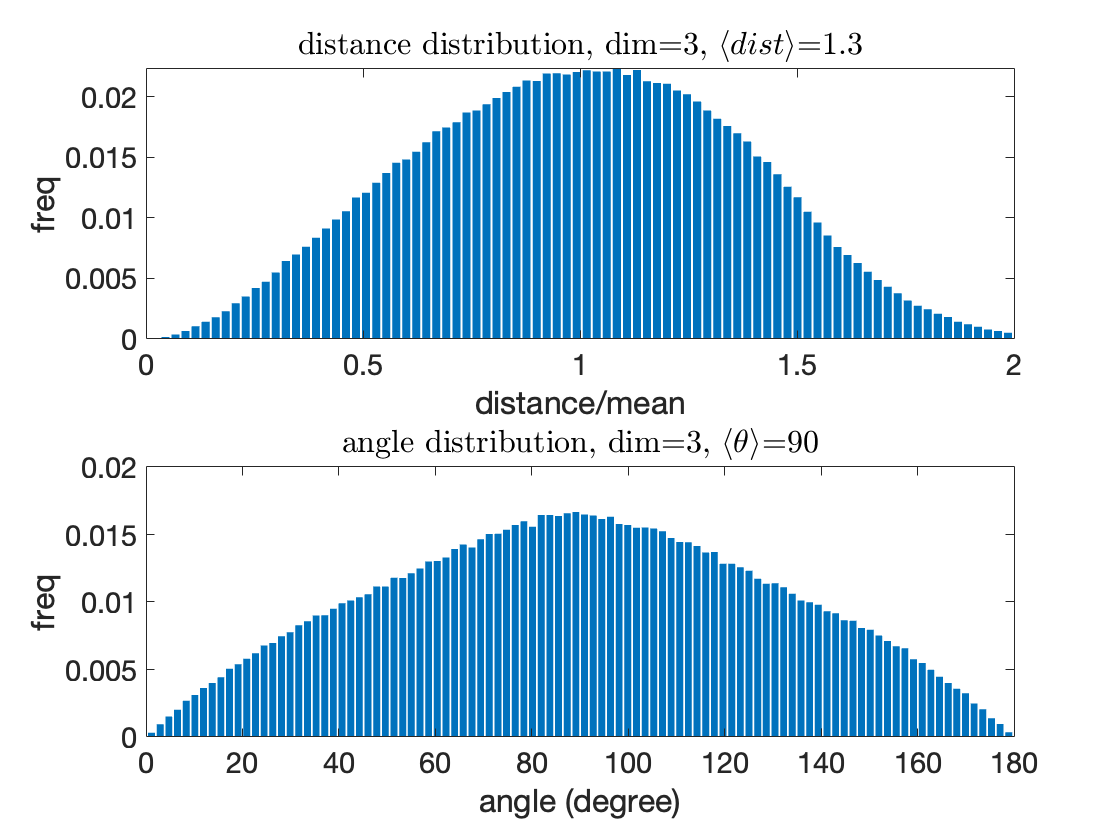

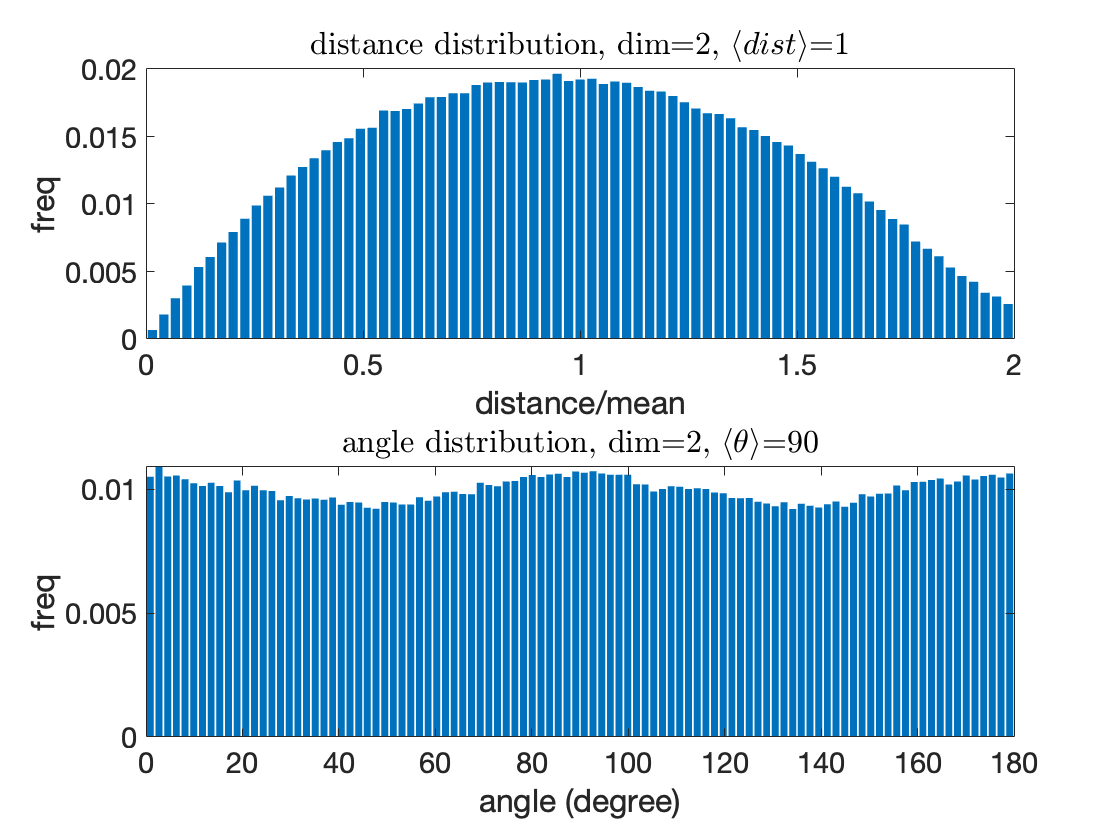

% parameters:
N=1000; % number of vectors, make it even
% font size:
set(0,'defaulttextfontsize',16); set(0,'defaultaxesfontsize',16);

% loop over dimension:
for d=[3,2]
  % setup a set of row vectors of uniformly distributed random
  % numbers between -1 and 1 - each row of X is a vector:
  X=2*(rand(N,d)-0.5);
  Xnorm=zeros(N,1);
  for i=1:N
    Xnorm(i)=sqrt(sum(X(i,:).*X(i,:)));
  end
  
  i=0;
  distances=NaN(N*(N-1)/2,1);
  angles=NaN(N*(N-1)/2,1);
  for n=1:N
    for m=2:(n-1)
      i=i+1;
      diff=X(n,:)-X(m,:); distances(i)=sqrt(sum(diff.*diff));
      angles(i)=acos(sum(X(n,:).*X(m,:))/(Xnorm(n)*Xnorm(m)));
    end
  end
  dist_mean=mean(distances(1:i));
  distances=distances(1:i)/dist_mean;
  angle_mean=mean(angles(1:i))*180/pi;
  angles=angles(1:i)*180/pi;

  figure; clf
  % plot distribution of distances:
  subplot(2,1,1);
  [counts,centers]=hist(distances,100);
  counts=counts/sum(counts);
  bar(centers,counts,'edgecolor','none');
  xlim([0,2]);
  title(sprintf('distance distribution, dim=%d, $\\langle{}dist\\rangle$=%.2g',d,dist_mean) ...
        ,'interpreter','LaTeX');
  xlabel('distance/mean');
  ylabel('freq');
  
  subplot(2,1,2);
  % plot distribution of angles:
  [counts,centers]=hist(angles,100);
  counts=counts/sum(counts);
  bar(centers,counts,'edgecolor','none');
  xlim([0,180]);
  title(sprintf('angle distribution, dim=%d, $\\langle\\theta\\rangle$=%.2g',d,angle_mean) ...
        ,'interpreter','LaTeX');
  xlabel('angle (degree)');
  ylabel('freq');
end

[Compare and discuss]

2b)

because []

2c) []

## 3

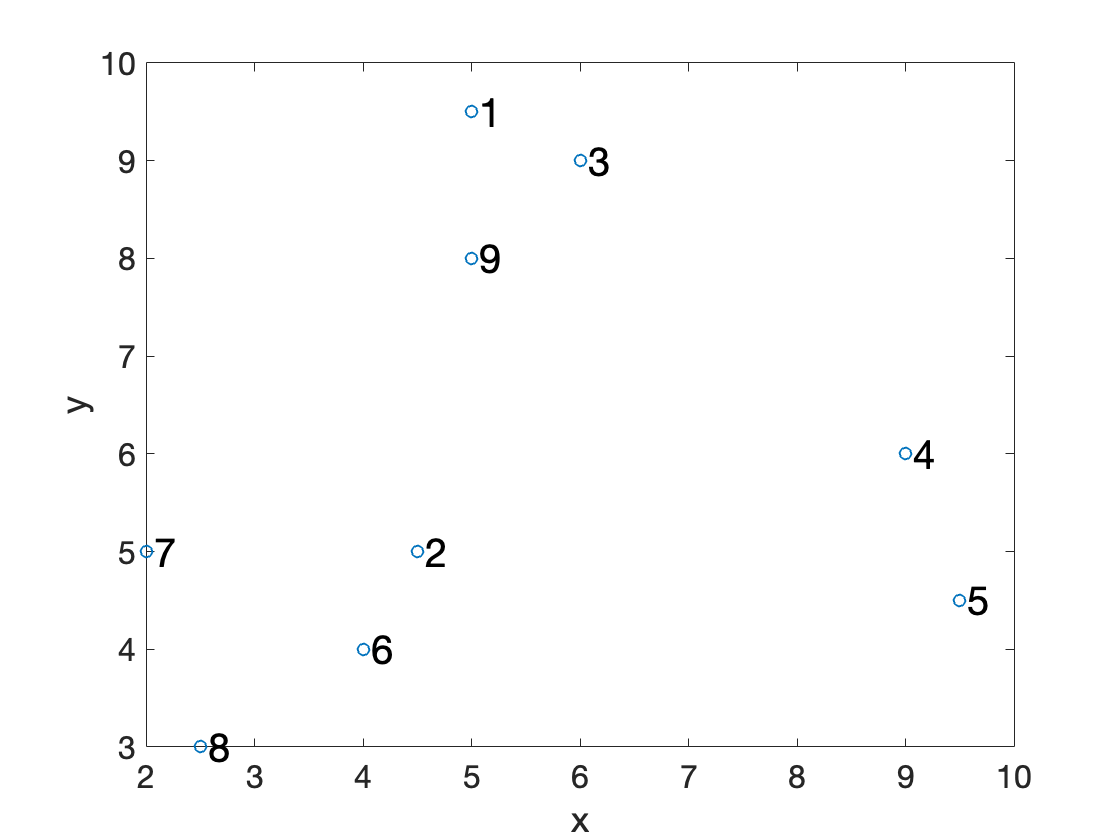

X=[ 5, 4.5, 6, 9, 9.5, 4, 2, 2.5, 5;
9.5, 5, 9, 6, 4.5, 4, 5, 3, 8];

figure;clf; scatter(X(1,:),X(2,:));
box on; hold on;xlabel('x');ylabel('y');
for ii=1:length(X(1,:))
text(X(1,ii)+0.07,X(2,ii),num2str(ii)...
    ,'FontSize',20);end

3a)

[hand calculation of first two mergings]

[dendrogram by hand]

The vertical distances in the dendrogram represent []

[best choice]

3b)

Y=pdist(X'); % Y is the Euclid distances of X
distances=squareform(Y), %[]

distances =          0    4.5277    1.1180    5.3151    6.7268    5.5902    5.4083    6.9642    1.5000
    4.5277         0    4.2720    4.6098    5.0249    1.1180    2.5000    2.8284    3.0414
    1.1180    4.2720         0    4.2426    5.7009    5.3852    5.6569    6.9462    1.4142
    5.3151    4.6098    4.2426         0    1.5811    5.3852    7.0711    7.1589    4.4721
    6.7268    5.0249    5.7009    1.5811         0    5.5227    7.5166    7.1589    5.7009
    5.5902    1.1180    5.3852    5.3852    5.5227         0    2.2361    1.8028    4.1231
    5.4083    2.5000    5.6569    7.0711    7.5166    2.2361         0    2.0616    4.2426
    6.9642    2.8284    6.9462    7.1589    7.1589    1.8028    2.0616         0    5.5902
    1.5000    3.0414    1.4142    4.4721    5.7009    4.1231    4.2426    5.5902         0


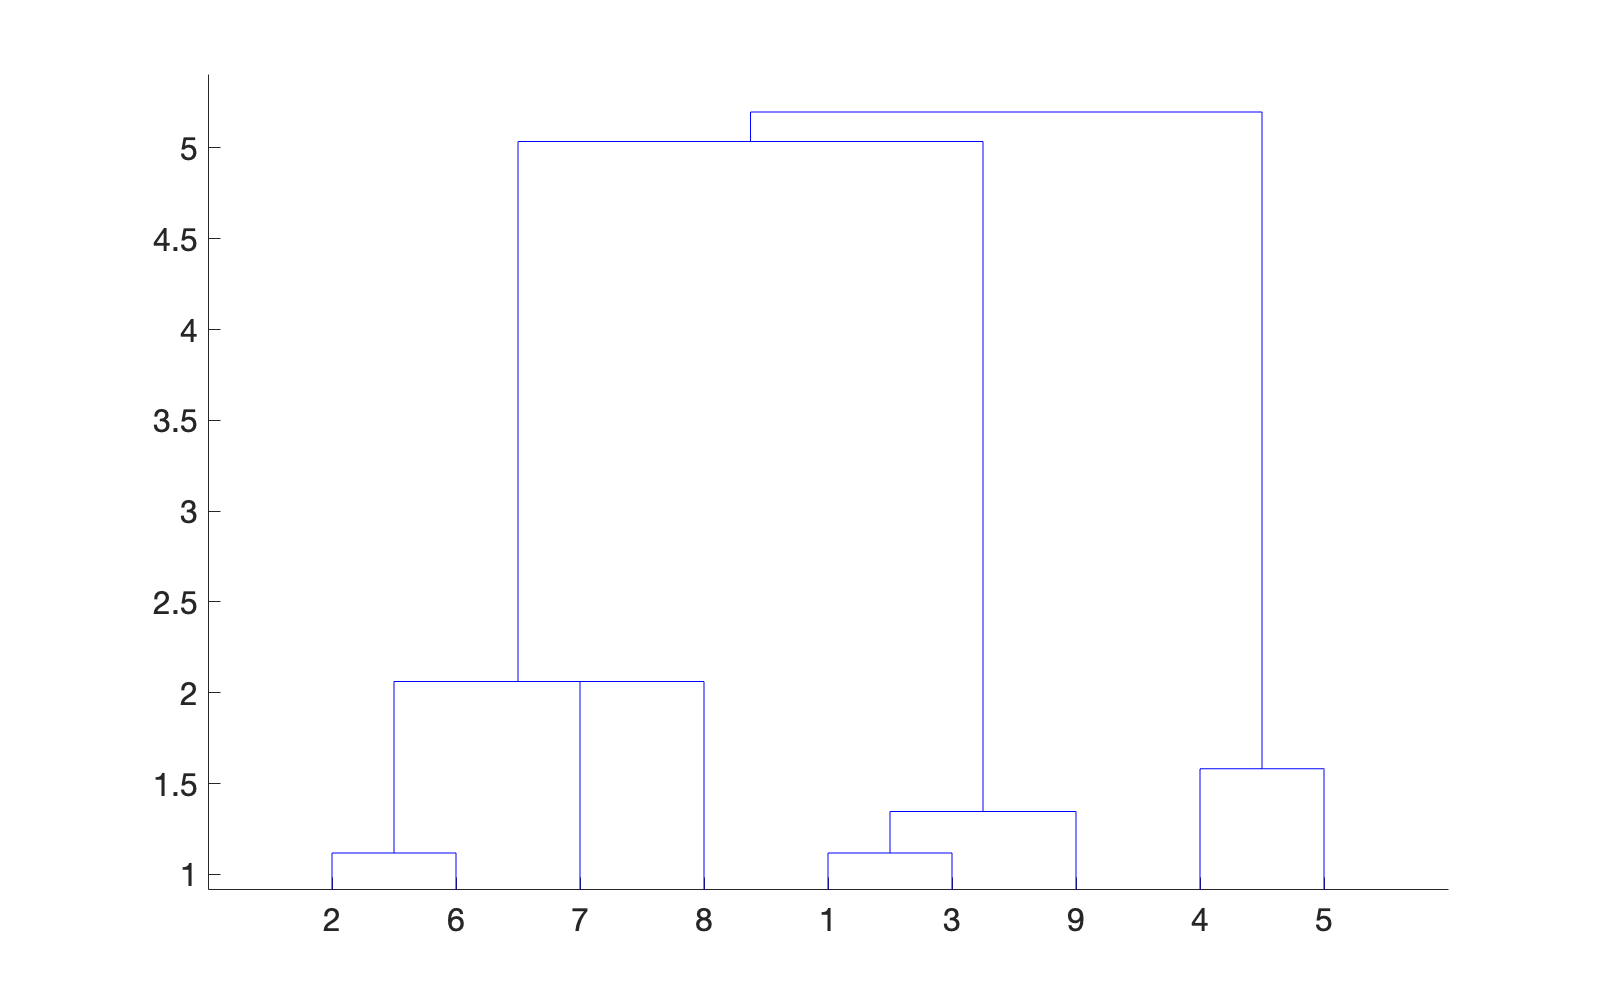

Z=linkage(Y,'centroid'); %[]
dendrogram(Z); % plot dendrogram from Z

k=3; % set k to 3
idx=cluster(Z,'maxclust',k)' %[]

idx =      1     2     1     3     3     2     2     2     1


3c)

distances

[]

Z

[]

idx

[]

dendrogram(Z)

[]

## 4

4a)

X=[ 5, 4.5, 6, 9, 9.5, 4, 2, 2.5, 5;
9.5, 5, 9, 6, 4.5, 4, 5, 3, 8];
